# HW3_2_1

First remove all open background.

close all;
clear;
clc;

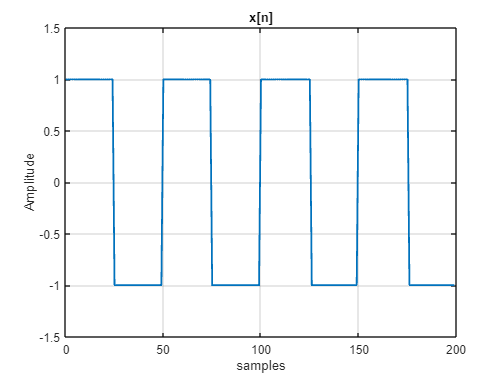

t = 0: 199;
T0 = 50;
duty_cycle = 0.5;
x = square(2 * pi * t/T0, duty_cycle * 100);
figure('Name', 'x[n]');
plot(t, x, 'LineWidth', 1.5);
ylim([-1.5, 1.5])
xlabel('samples');
ylabel('Amplitude');
title('x[n]');
grid on;

## **H1**

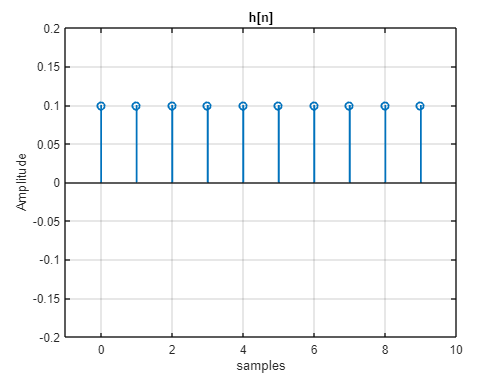

h1 = 0.1*ones(1, 10);
figure('Name', 'h1[n]');
stem((0: 9), h1, 'LineWidth', 1.5);
xlim([-1, 10])
ylim([-0.2, 0.2])
xlabel('samples');
ylabel('Amplitude');
title('h[n]');
grid on;

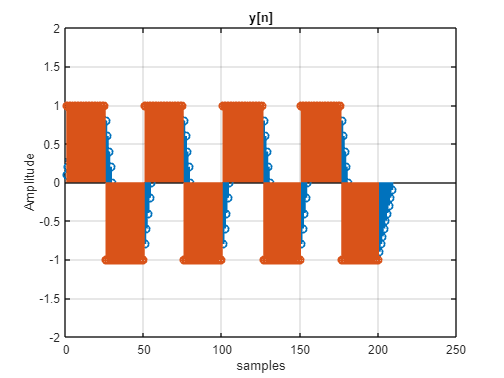

y = myConv(h1, x);
figure('Name', 'y1[n]');
stem(y, 'LineWidth', 1.5); hold on;
stem(x, 'LineWidth', 1.5); hold off;
ylim([-2, 2])
xlabel('samples');
ylabel('Amplitude');
title('y[n]');
grid on;

As it is obvious sum of x with delay could make ramp in special parts and in another part which there is no high ratio freq in x the output is stable, so it works like filter.

## **H2**

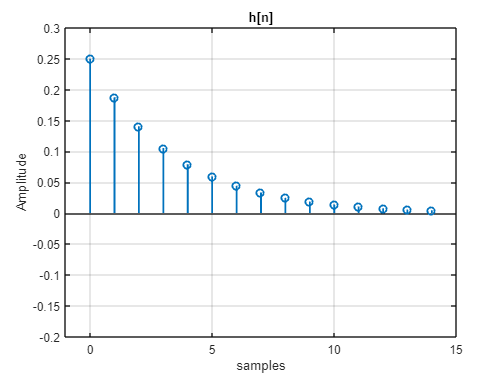

h2 = ones(1, 15)*3/4;
h2 = 1/4*(h2 .^ (0: 14));
figure('Name', 'h2[n]');
stem((0: 14), h2, 'LineWidth', 1.5);
xlim([-1, 15])
ylim([-0.2, 0.3])
xlabel('samples');
ylabel('Amplitude');
title('h[n]');
grid on;

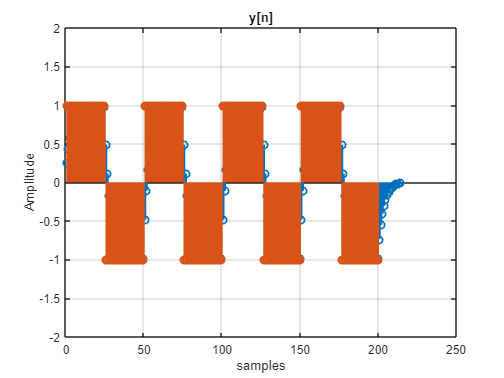

y = myConv(h2, x);
figure('Name', 'y2[n]');
stem(y, 'LineWidth', 1.5); hold on;
stem(x, 'LineWidth', 1.5); hold off;
ylim([-2, 2])
xlabel('samples');
ylabel('Amplitude');
title('y[n]');
grid on;

## **H3**

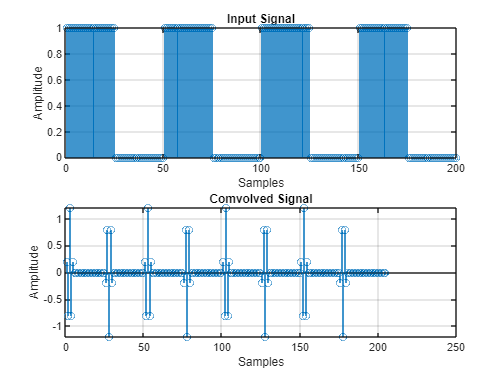

x = [ones(1, 25) zeros(1, 25)];
t = 0:1:199;
for i = 1:3
   x = [x ones(1, 25) zeros(1, 25)];
end
y = myConv([1, -1], x);
for i = 1:4
   y = myConv([1, -1], y);
end
y = 1/5 * y;
figure('Name', 'Convolution');
subplot(2,1,1)
stem(x);
xlabel('Samples');
ylabel('Amplitude');
title('Input Signal');
grid on;

subplot(2,1,2)
stem(y);
xlabel('Samples');
ylabel('Amplitude');
grid on;
title('Comvolved Signal');

define myConv function:

function convOut = myConv(h, x)
   size_x   = length(x);
   h_pad    = [h zeros(1, size_x - 1)];
   c        = [h(1) zeros(1, size_x - 1)];
   H        = toeplitz(c, h_pad);
   convOut  = x * H;
end